## Linear parametrization

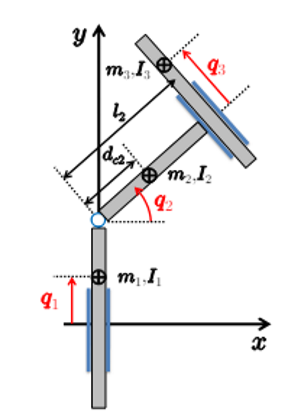

syms q1 q2 q3 l2 real    % joint coordinates
syms dq1 dq2 dq3 real % joint velocities
syms d I2 real

% Joint 2
x2 = d*cos(q2);
y2 = q1 + d*sin(q2);
z2 = 0;  

% Velocity components (vx2, vy2, vz2)
vx2 = diff(x2, q1)*dq1 + diff(x2, q2)*dq2 + diff(x2, q3)*dq3;
vy2 = diff(y2, q1)*dq1 + diff(y2, q2)*dq2 + diff(y2, q3)*dq3;
vz2 = diff(z2, q1)*dq1 + diff(z2, q2)*dq2 + diff(z2, q3)*dq3;

disp('Joint 2:');

Joint 2:


disp('p2 = [x2; y2; z2] =');

p2 = [x2; y2; z2] =


disp([x2; y2; z2]);

$$\left(\begin{array}{c} d\,\cos\left(q_{2}\right)\\ q_{1}+d\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

disp('Velocity (vx2, vy2, vz2) =');

Velocity (vx2, vy2, vz2) =


disp([vx2; vy2; vz2]);

$$\left(\begin{array}{c} -d\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}+d\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\\ 0 \end{array}\right)$$


vect1 = [vx2 vy2 vz2];
vect2 = [vx2; vy2; vz2];
pro   = vect1 * vect2;

% Joint 3
x3 = l2*cos(q2) - q3*sin(q2);
y3 = q1 + l2*sin(q2) + q3*cos(q2);
z3 = 0;  

% Velocity components (vx3, vy3, vz3)
vx3 = diff(x3, q1)*dq1 + diff(x3, q2)*dq2 + diff(x3, q3)*dq3;
vy3 = diff(y3, q1)*dq1 + diff(y3, q2)*dq2 + diff(y3, q3)*dq3;
vz3 = diff(z3, q1)*dq1 + diff(z3, q2)*dq2 + diff(z3, q3)*dq3;

disp('Joint 3:');

Joint 3:


disp('p3 = [x3; y3; z3] =');

p3 = [x3; y3; z3] =


disp([x3; y3; z3]);

$$\left(\begin{array}{c} l_{2}\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right)\\ q_{1}+q_{3}\,\cos\left(q_{2}\right)+l_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

disp('Velocity (vx3, vy3, vz3) =');

Velocity (vx3, vy3, vz3) =


disp([vx3; vy3; vz3]);

$$\left(\begin{array}{c} -{\mathrm{dq}}_{2}\,\left(q_{3}\,\cos\left(q_{2}\right)+l_{2}\,\sin\left(q_{2}\right)\right)-{\mathrm{dq}}_{3}\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\,\left(l_{2}\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right)\right)+{\mathrm{dq}}_{3}\,\cos\left(q_{2}\right)\\ 0 \end{array}\right)$$


vect3 = [vx3 vy3 vz3];
vect4 = [vx3; vy3; vz3];
pr3 = simplify(vect3 * vect4, 'Steps',100);

% INERTIA MATRIX M(q)
syms m1 m2 m3 I3 real

% Total kinetic energy:
%  T = (1/2)*m1*(dq1^2)
%      + (1/2)*m2*pro    + (1/2)*I2*(dq2^2)
%      + (1/2)*m3*pr3    + (1/2)*I3*(dq2^2)
%
%  'pro' and 'pr3' are the squared speeds of link2's and link3's CoM
%  computed above.

T = 0.5*m1*(dq1^2) ...
  + 0.5*m2*pro + 0.5*I2*(dq2^2) ...
  + 0.5*m3*pr3 + 0.5*I3*(dq2^2);

% Compute the 3×3 inertia matrix via second derivatives of T w.r.t. dq1,dq2,dq3
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);
M13 = diff(diff(T, dq1), dq3);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);
M23 = diff(diff(T, dq2), dq3);

M31 = diff(diff(T, dq3), dq1);
M32 = diff(diff(T, dq3), dq2);
M33 = diff(diff(T, dq3), dq3);

M = [M11, M12, M13;
     M21, M22, M23;
     M31, M32, M33];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\begin{array}{l} \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & \sigma_{1} & m_{3}\,\cos\left(q_{2}\right)\\ \sigma_{1} & m_{2}\,d^{2}+m_{3}\,{l_{2}}^{2}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3} & l_{2}\,m_{3}\\ m_{3}\,\cos\left(q_{2}\right) & l_{2}\,m_{3} & m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{3}\,\left(2\,l_{2}\,\cos\left(q_{2}\right)-2\,q_{3}\,\sin\left(q_{2}\right)\right)}{2}+d\,m_{2}\,\cos\left(q_{2}\right) \end{array}$$


M_para = [...
    a1,                                     a3*(l2*cos(q2) - q3*sin(q2)) + a4*cos(q2),   a3*cos(q2);
    a3*(l2*cos(q2) - q3*sin(q2)) + a4*cos(q2),   a2 + a3*(l2^2 + q3^2),                  a3*l2;
    a3*cos(q2),                              a3*l2,                                     a3       ];

q  = [q1; q2; q3];
dq = [dq1; dq2; dq3];

[C, c_vec] = computeCoriolis(M, q, dq);

disp('NO PARAMETRIZATION Coriolis matrix C(q,dq) =');

NO PARAMETRIZATION Coriolis matrix C(q,dq) =


disp(C);

$$\left(\begin{array}{ccc} 0 & -{\mathrm{dq}}_{2}\,\left(\frac{m_{3}\,\left(2\,q_{3}\,\cos\left(q_{2}\right)+2\,l_{2}\,\sin\left(q_{2}\right)\right)}{2}+d\,m_{2}\,\sin\left(q_{2}\right)\right)-{\mathrm{dq}}_{3}\,m_{3}\,\sin\left(q_{2}\right) & -{\mathrm{dq}}_{2}\,m_{3}\,\sin\left(q_{2}\right)\\ 0 & {\mathrm{dq}}_{3}\,m_{3}\,q_{3} & {\mathrm{dq}}_{2}\,m_{3}\,q_{3}\\ 0 & -{\mathrm{dq}}_{2}\,m_{3}\,q_{3} & 0 \end{array}\right)$$


disp('NO PARAMETRIZATION Vector c(q,dq) = C(q,dq)*dq =');

NO PARAMETRIZATION Vector c(q,dq) = C(q,dq)*dq =


disp(c_vec);

$$\left(\begin{array}{c} -{\mathrm{dq}}_{2}\,\left({\mathrm{dq}}_{2}\,\left(\frac{m_{3}\,\left(2\,q_{3}\,\cos\left(q_{2}\right)+2\,l_{2}\,\sin\left(q_{2}\right)\right)}{2}+d\,m_{2}\,\sin\left(q_{2}\right)\right)+{\mathrm{dq}}_{3}\,m_{3}\,\sin\left(q_{2}\right)\right)-{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,m_{3}\,\sin\left(q_{2}\right)\\ 2\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,m_{3}\,q_{3}\\ -{{\mathrm{dq}}_{2}}^{2}\,m_{3}\,q_{3} \end{array}\right)$$


[C2, c_vec2] = computeCoriolis(M_para, q, dq);

disp('PARAMETRIZATION Coriolis matrix C(q,dq) =');

PARAMETRIZATION Coriolis matrix C(q,dq) =


disp(C2);

$$\left(\begin{array}{ccc} 0 & -{\mathrm{dq}}_{2}\,\left(a_{3}\,\left(q_{3}\,\cos\left(q_{2}\right)+l_{2}\,\sin\left(q_{2}\right)\right)+a_{4}\,\sin\left(q_{2}\right)\right)-a_{3}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}\right) & -a_{3}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\\ 0 & a_{3}\,{\mathrm{dq}}_{3}\,q_{3} & a_{3}\,{\mathrm{dq}}_{2}\,q_{3}\\ 0 & -a_{3}\,{\mathrm{dq}}_{2}\,q_{3} & 0 \end{array}\right)$$


disp('PARAMETRIZATION Vector c(q,dq) = C(q,dq)*dq =');

PARAMETRIZATION Vector c(q,dq) = C(q,dq)*dq =


disp(c_vec2);

$$\left(\begin{array}{c} -{\mathrm{dq}}_{2}\,\left({\mathrm{dq}}_{2}\,\left(a_{3}\,\left(q_{3}\,\cos\left(q_{2}\right)+l_{2}\,\sin\left(q_{2}\right)\right)+a_{4}\,\sin\left(q_{2}\right)\right)+a_{3}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}\right)\right)-a_{3}\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}\right)\\ 2\,a_{3}\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,q_{3}\\ -a_{3}\,{{\mathrm{dq}}_{2}}^{2}\,q_{3} \end{array}\right)$$


% Regressor matrix
ddq = [ddq1; ddq2; ddq3;];

Ya = M_para*ddq

$$Ya = \begin{array}{l} \left(\begin{array}{c} a_{1}\,{\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{2}\,\sigma_{1}+a_{3}\,{\mathrm{ddq}}_{3}\,\cos\left(q_{2}\right)\\ {\mathrm{ddq}}_{1}\,\sigma_{1}+{\mathrm{ddq}}_{2}\,\left(a_{2}+a_{3}\,\left({l_{2}}^{2}+{q_{3}}^{2}\right)\right)+a_{3}\,{\mathrm{ddq}}_{3}\,l_{2}\\ a_{3}\,{\mathrm{ddq}}_{3}+a_{3}\,{\mathrm{ddq}}_{2}\,l_{2}+a_{3}\,{\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\left(l_{2}\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right)\right)+a_{4}\,\cos\left(q_{2}\right) \end{array}$$


% Dynamic symbols
dynamic_symbols = [a1, a2, a3, a4];

Y = extract_Y_v3(Ya, dynamic_symbols);

disp('Regressor Matrix Y:');

Regressor Matrix Y:


disp(Y);

$$\left(\begin{array}{cccc} {\mathrm{ddq}}_{1} & 0 & {\mathrm{ddq}}_{2}\,\left(l_{2}\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right)\right)+{\mathrm{ddq}}_{3}\,\cos\left(q_{2}\right) & {\mathrm{ddq}}_{2}\,\cos\left(q_{2}\right)\\ 0 & {\mathrm{ddq}}_{2} & {\mathrm{ddq}}_{3}\,l_{2}+{\mathrm{ddq}}_{1}\,\left(l_{2}\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right)\right)+{\mathrm{ddq}}_{2}\,\left({l_{2}}^{2}+{q_{3}}^{2}\right) & {\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right)\\ 0 & 0 & {\mathrm{ddq}}_{3}+{\mathrm{ddq}}_{2}\,l_{2}+{\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right) & 0 \end{array}\right)$$

function Y = extract_Y_v3(Ya, dynamic_symbols)
    % Estrae la matrice di regressione Y da un'espressione Ya lineare
    % nei simboli elencati in dynamic_symbols.
    %
    % Ya              : espressione simbolica (ad es. M*ddq + c + G)
    % dynamic_symbols : array contenente [a1, a2, ..., aN]
    %
    % Output: Y       : matrice che, moltiplicata per [a1; a2; ...; aN],
    %                   restituisce l'originale Ya.

    % Inizializzazione
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    % Assicuriamoci di avere dynamic_symbols come array riga
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i = 1:Y_columns
        % Costruisco un array di sostituzione: tutti zeri tranne un 1
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;

        % Sostituisco in Ya: a_i=1, gli altri=0
        Yi = subs(Ya, dynamic_symbols, subs_array);

        % Concateno in colonna
        Y = [Y, Yi];
    end
end

function [C, c_vec] = computeCoriolis(M, q, dq)
% COMPUTECORIOLIS Computes the Coriolis matrix C(q,dq) and vector c(q,dq) = C*dq
% from a symbolic inertia matrix M(q) and symbolic vectors q, dq.

n = length(q);
C = sym(zeros(n, n));

for i = 1:n
    for j = 1:n
        temp = 0;
        for k = 1:n
            temp = temp + 0.5 * ( diff(M(i,j), q(k)) + diff(M(i,k), q(j)) - diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(temp);
    end
end

c_vec = simplify(C * dq);
end

